# Chapter 2 Practice Problems

Problems from the book

clear; clc;

## Problem 2.5 - Humps

The MATLAB humps function defines a curve w/ 2 maxima of unequal height over the interval [0,2]. Use MATLAB to generate a plot of f(x) versus x for x = [0:1/256:2]. Employ the minimum number of periods to do vector operations to generate f(x) values.

i.e. just take eq. from book and show it in Matlab

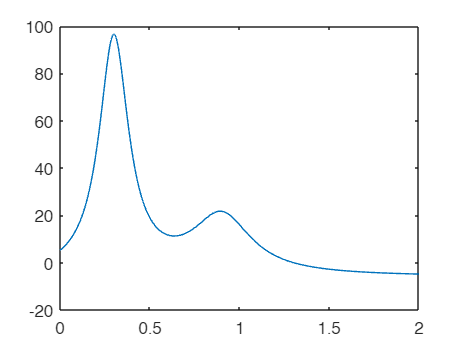

x = [0:1/256:2];
y = 1./((x-0.3).^2+0.01) + 1./((x-0.9).^2+0.04) - 6; % no need for @(x), then would do f(x) in plot
    % . operator necessary for / and ^
plot(x, y);
hold off;

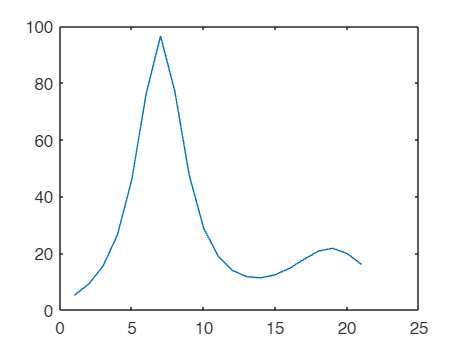


plot(humps); % dif x scale ig

## Problem 2.6 - Colon Notation

Use the linspace function to create vectors identical to the following created with the colon notation.

a. t = 4:6:35

b. x = -4:2

% a
t_orig = 4:6:35 % helpful just to think thru: 4 10 16... 34

t_orig =      4    10    16    22    28    34



% NOT t = linspace(4,35,6)
t = linspace(4,34,6)

t =      4    10    16    22    28    34



% b
x_orig = -4:2 % auto by 1***

x_orig =     -4    -3    -2    -1     0     1     2



% NOT x_b = linspace(-4,2) % 100 implied
numBtwn = (2+4);
x_b = linspace(-4,2, numBtwn+1)

x_b =     -4    -3    -2    -1     0     1     2


## Problem 2.7 - Linspace Notation

Go from linspace -> colon operators

a. v = linspace(-2,1.5,8)

b. r = linspace(8,4.5,8)

% a
v_orig = linspace(-2,1.5,8)

v_orig =    -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000


    % goes by 0.5
v = -2:0.5:1.5

v =    -2.0000   -1.5000   -1.0000   -0.5000         0    0.5000    1.0000    1.5000



% b
r_orig = linspace(8,4.5,8)

r_orig =     8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000    4.5000


    % goes by -0.5
r = 8:-0.5:4.5

r =     8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000    4.5000


## Problem 2.15 - Solve Eq for Table

Manning's equation can be used to compute the velocity of water in a rectangular open channel.

*U* = velocity (m/s), *S *= channel slope, *n *= roughness coeff, *B *= width (m), *H* = depth (m).

Have a table w/ data for the five channels. Store the values in a matrix, where each row = one channel, each column reps one of parameters.

Write a single-line MATLAB statement to compute a column vector containing the velocities based on the values in the parameter matrix.

A = [0.035 0.0001 10 2;
    0.020 0.0002 8 1;
    0.015 0.0010 20 1.5;
    0.030 0.0007 24 3;
    0.022 0.0003 15 2.5]; % table given [n S B H]

n = A(:,1); % roughness coeff
S = A(:,2); % channel slope
B = A(:,3); % width (m)
H = A(:,4); % depth (m)

U = sqrt(S)./n.*(B.*H./(B+2*H)).^(2/3) % velocity (m/s)

U =     0.3624
    0.6094
    2.5167
    1.5809
    1.1971


    % Don't forget .^(2/3)
    % NOTE: could put all in U w/o n,S,B,H, but it helps me understand

## Problem 2.23a - Easy

Exactly what will be displayed after the following matlab commands are typed?

a. x = 5; % Nothing

x^3; % Nothing, ans = 15 tho

y = 8 - x % y = 3 % bc the x^3 is not saved to anything

x = 5;
x^3; % not saved to anything
y = 8-x % 8 - 5

y = 3

b. q = 4:2:12;

r = [7 8 4; 3 6 -5];

sum(q) * r(2,3)

q = 4:2:12;
r = [7 8 4; 3 6 -5];
sum(q) * r(2,3) % (4+6+...+12) * -5

ans = -200

## Problem 2.18 - Plot -.

Given wind tunnel data for force F versus velocity v. Given ftn F to describe. Use Matlab to create a plot showigng the data (circular magenta symbols) and the function (black dash-dotted line). Plot the ftn for v = 0 to 100 m/s and label the plot's axes.

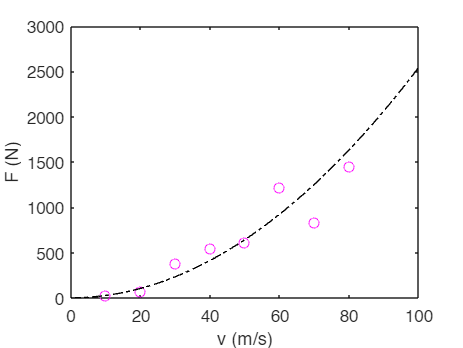

v = 10:10:80;
F = [25 70 380 550 610 1220 830 1450];

vf = 0:100;
Ff = 0.2741*vf.^1.9842;
plot(v, F, 'om', vf, Ff, '-.k'); % could also do 2 separate, hold on
xlabel('v (m/s)');
ylabel('F (N)');

## 2.7 Case Study - More Bungee

% Data
m = [83.6 60.2 72.1 91.1 92.9 65.3 80.9];
vt = [53.4 48.5 50.9 55.7 54 47.7 51.1];
g = 9.81;

% Get Drag Coeff
cd = g*m./vt.^2

cd =     0.2876    0.2511    0.2730    0.2881    0.3125    0.2815    0.3039



% Now Generate Stats for results ***
cd_avg = mean(cd), cd_min = min(cd); cd_max = max(cd)

cd_avg = 0.2854

cd_max = 0.3125


% Use avg to predict terminal velocity
vpred = sqrt(g*m/cd_avg) % no periods needed

vpred =    53.6065   45.4897   49.7831   55.9595   56.5096   47.3774   52.7338


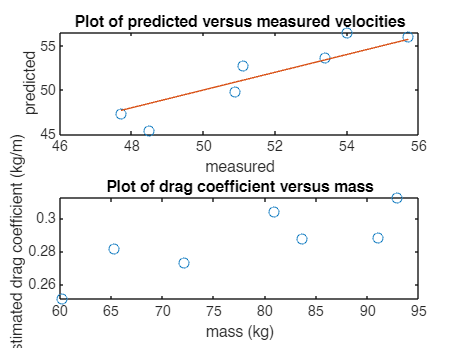


% Plot versus actual measured terminal velos
subplot(2,1,1); plot(vt, vpred, 'o', vt, vt);
xlabel('measured');
ylabel('predicted');
title('Plot of predicted versus measured velocities');
    % seems pretty good, but also low for low vals, high for high vals
    % Might be a trend in the drag coefficients instead of being constant
    % Look at drag coeffs v mass

subplot(2,1,2); plot(m,cd, 'o');
xlabel('mass (kg)');
ylabel('Estimated drag coefficient (kg/m)');
title('Plot of drag coefficient versus mass');

    % Can see drag coeffs seem to increase as mass />
    % May need to improve the model, or do more experiments

% cd = C_D*rho*A/(2)

## In-Class Activity

Write a MATLAB expression to compute and display the values of a vector x using the following equation. Assume that y and z are vector quantities of equal length and a and b are scalars.

a = 5; b = 10; y = [1 2; 3 4]; z = [5 6; 7 8];
x = y.*(a+b*z).^1.8./(z.*(1-y));

x =        Inf -611.1148
 -508.2806 -495.2253
